# Frequecy Features  

Prerequisite:  Review how to apply FFT of signals

Frequency Features of 

- Frequency Center

- RMS frequency

- Root variance frequency

> Need to use  getFFT.m   See FFT_Exercise.mlx

## Dataset

### Generate Signals

A signal with a sampling frequency of 1 kHz and a signal duration of 1 second.

Form a signal containing a 50 Hz sinusoid and 120Hz sinusoid 

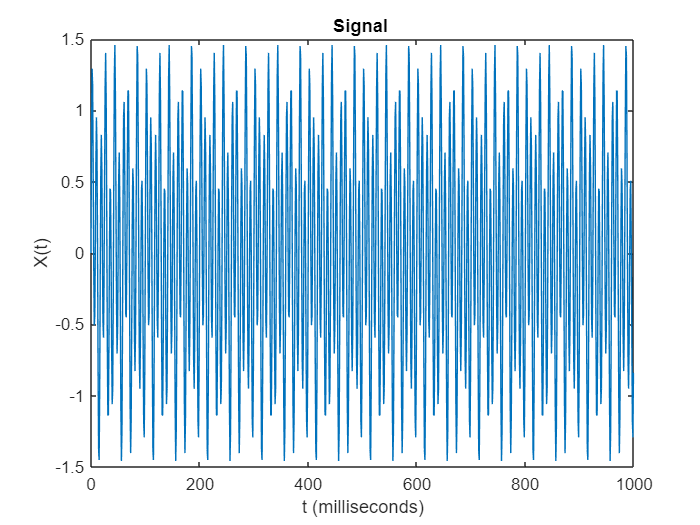

close all
clear 

Fs = 1000;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
N = 1000;             % Length of signal
t = (0:N-1)*T;        % Time vector

% Information Signal 
fa=50;                % 10Hz signal
fa2=120;              % 55Hz signal
X = 0.0 + 0.5* sin(2.0*pi*fa*t)+1*sin(2.0*pi*fa2*t); 

% Plot signals
figure()
plot(1000*t,X)
title('Signal ')
xlabel('t (milliseconds)')
ylabel('X(t)')

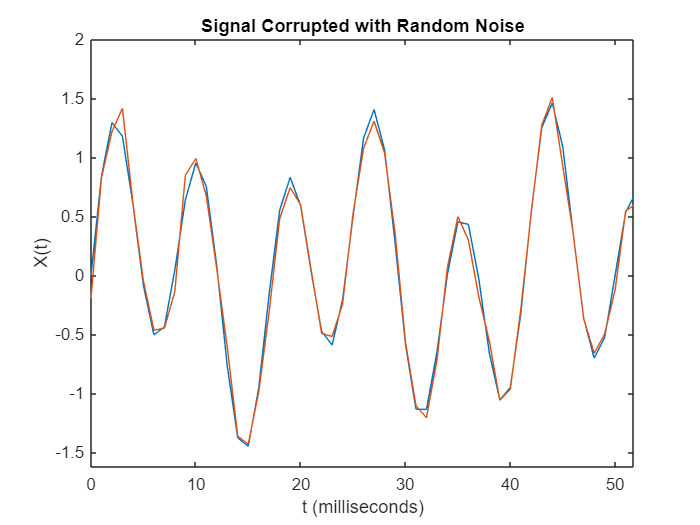

% Noise
noise=0.1 * randn(size(t));

% Mixed Signal
Xm = X + noise; 

% Plot signals
figure(1)
plot(1000*t, X, 1000*t, Xm)
title('Signal Corrupted with Random Noise')
xlabel('t (milliseconds)')
ylabel('X(t)')
xlim([0 50])

## Exercise 1: Frequency Features (simple)

- Frequency Center

- RMS frequency

- Root variance frequency

### 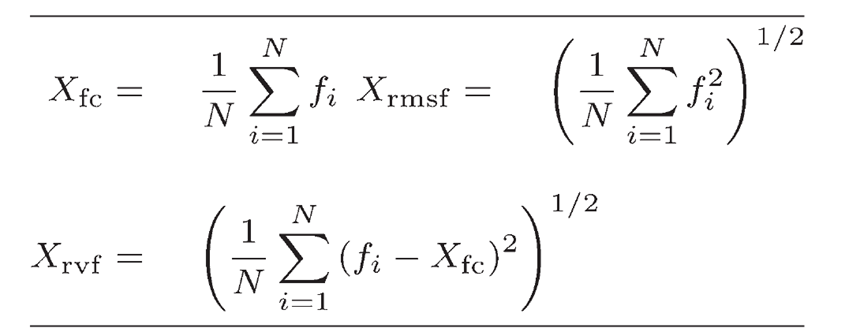

### FFT analysis

%% Input for FFT
x=X;    %x=Xm;
L=length(x);

%%% Apply FFT of x
% single-sided spectrum P1

[f, P] = getFFT(X, L, Fs);  

Plot single-sided spectrum P

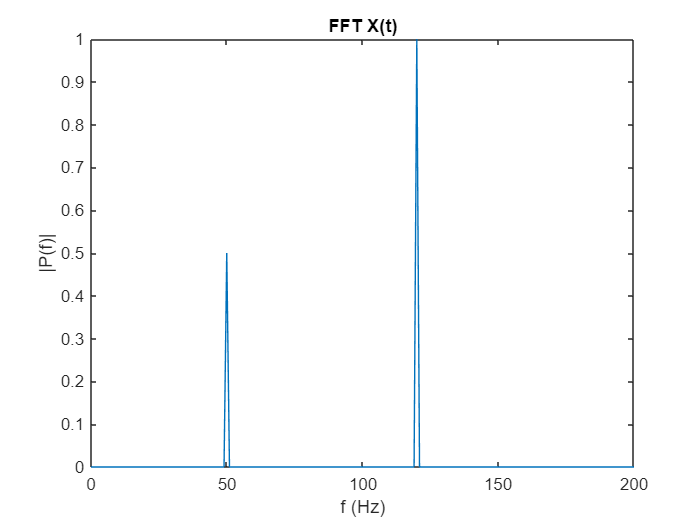

figure
plot(f,P) 
title('FFT X(t)')
xlabel('f (Hz)')
ylabel('|P(f)|')
xlim([0 200])

### Frequency features

% x:        Input data
% xfeature: Table for feature of x

F = P;        %=Xm
N = length(F);

% Create table variable xfeature
xfeature = table;

**Frequency Center**

xfeature.fc = sum(P)/N;

**RMS frequency**

xfeature.rmsf = sqrt(sum(P.^2)/N);

**Root variance frequency**

xfeature.rvf = sqrt(sum((P-xfeature.fc).^2)/N);

## Exercise 2

Compare the time-domain features with and without noise added.

## Exercise 3

Create a function  that returns time-domain features in table form

Example: 

[f, P] = getFFT(x,L, Fs);

xfeature2 = freqFeatures(P)

xfeature2 = 1×3 table
       fc        rmsf        rvf  
    ________    _______    _______

    0.002994    0.04995    0.04986
